# METODO DE NEWTON Y JOSEPH RAPHSON

clc, clear;
format long g;
syms x;

**APROXIMACIÓN INICIAL**

p_0 = 4;

**INGRESAR LA TOLERACIA:**

Tol     = 0.0001;

**INGRESAR EL NUMERO DE ITERACIONES:**

Num_it  = 30;

**INGRESAR LA ECUACÍON x=g(x):**

**RECORDANDO QUE ΔPSI = P0-Pt**

f_x= 0.45*0.9+9.36*log10(x+1)-0.2+ ( (log10(3.5/(4.2-1.5)))/ (0.4+ 1094/(x+1)^5.19) )+2.32*log10(8952.1)-8.07-log10(2.35*10^7);

**=========================================================================================================================**

**=========================================================================================================================**

df_x= diff(f_x)

$$df\_x = \frac{234}{25\,\log\left(10\right)\,\left(x+1\right)}+\frac{2305551623892734709141}{3602879701896396800\,{\left(x+1\right)}^{619/100}\,{\left(\frac{1094}{{\left(x+1\right)}^{519/100}}+\frac{2}{5}\right)}^{2}}$$

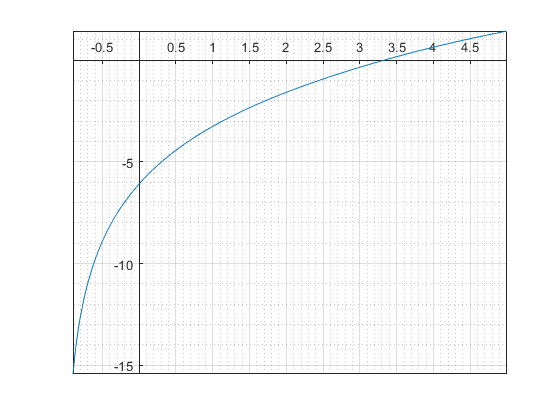

n=[1 2];
x_0=[1 2];
g_x=[1 2];
error_=[0 2];

fplot(f_x);
hold on;
hold off;
grid on;
grid minor;
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

f= @(x) eval(f_x);
g= @(x) eval(df_x);
i=1;

while(i <= Num_it)
    p=p_0-(f(p_0)/g(p_0));    
           
    n(i)=i;
    x_0(i)= p_0;
    g_x(i)= p;
    error_(i)= p-p_0;
    
     if((f(p_0)==0) || (abs(p-p_0)<Tol))
        disp(p);
        break;
     else        
        p_0=p;
    end
     i=i+1;
end

          3.32089527345312



n;


